clc; close all; clear all; 

% Initial reading of the Wine data
wines = readtable('winequality-red.csv','VariableNamingRule','preserve');
wines.Index = (1:height(wines))'; %% index data


% Summary to see basic statistics of variables
summary(wines);

Variables:

    fixed acidity: 1599×1 double

        Values:

            Min          4.6  
            Median       7.9  
            Max         15.9  

    volatile acidity: 1599×1 double

        Values:

            Min         0.12  
            Median      0.52  
            Max         1.58  

    citric acid: 1599×1 double

        Values:

            Min            0  
            Median      0.26  
            Max            1  

    residual sugar: 1599×1 double

        Values:

            Min          0.9  
            Median       2.2  
            Max         15.5  

    chlorides: 1599×1 double

        Values:

            Min        0.012  
            Median     0.079  
            Max        0.611  

    free sulfur dioxide: 1599×1 double

        Values:

            Min           1   
            Median       14   
            Max          72   

    

% Create Header variable
header = wines.Properties.VariableNames;
disp(header);

    {'fixed acidity'}    {'volatile acidity'}    {'citric acid'}    {'residual sugar'}    {'chlorides'}    {'free sulfur dioxide'}    {'total sulfur dioxide'}    {'density'}    {'pH'}    {'sulphates'}    {'alcohol'}    {'quality'}    {'Index'}



fixed acidity


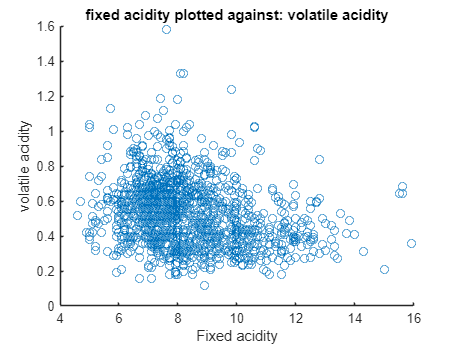

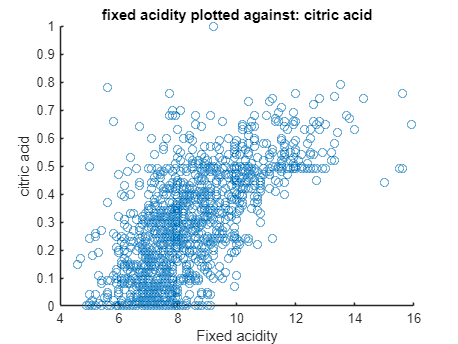

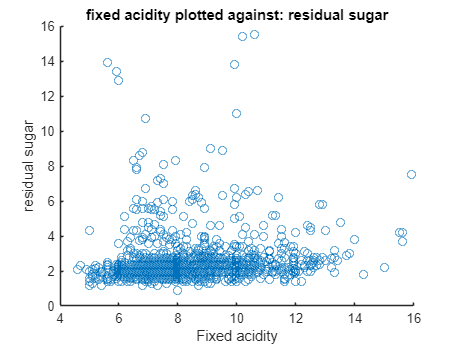

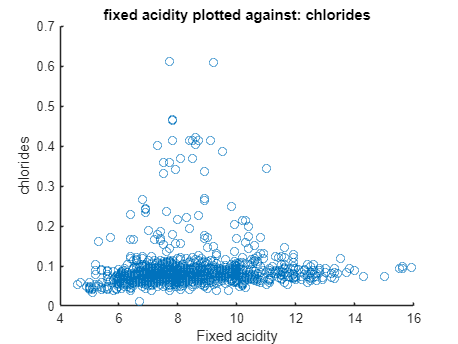

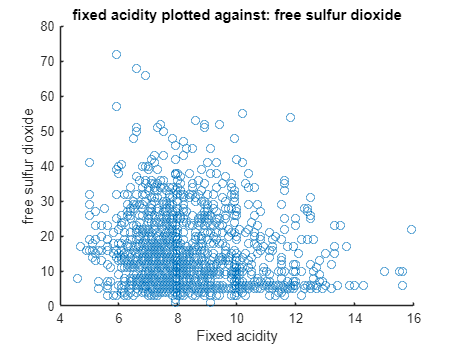

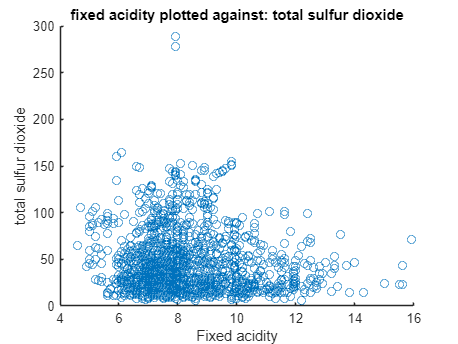

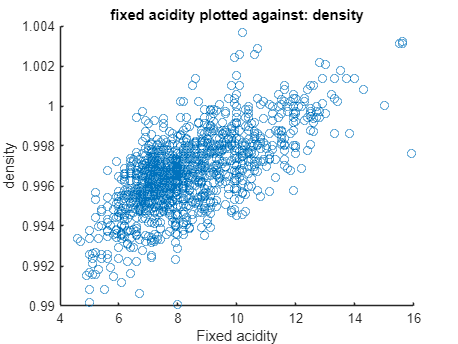

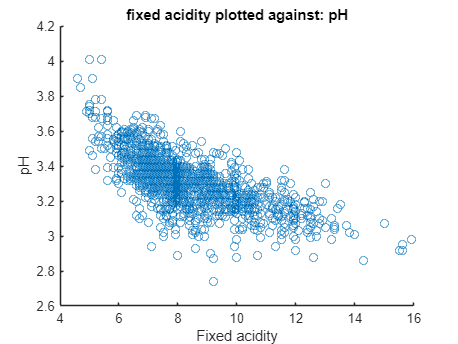

%% Fixed acidity
for i = 1:length(header)
    figure;
    if wines.Properties.VariableNames{i} == "fixed acidity"
        continue
    end
     scatter(wines.("fixed acidity"), wines{:,i});
     xlabel('Fixed acidity');
     ylabel(header{i});
     title(['fixed acidity plotted against: ', header{i}]);

end

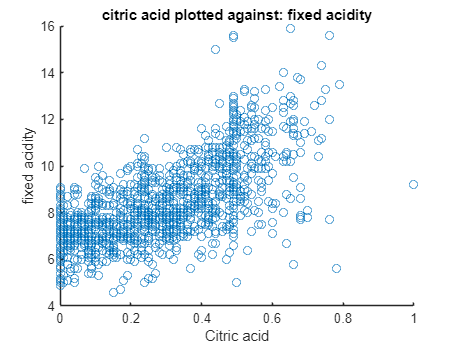

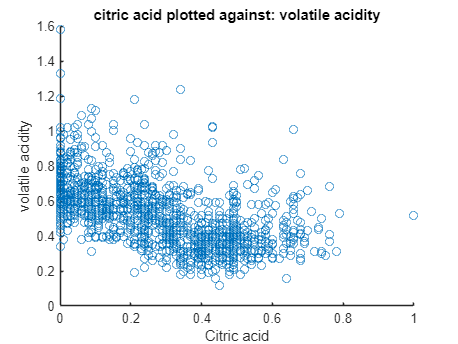

citric acid


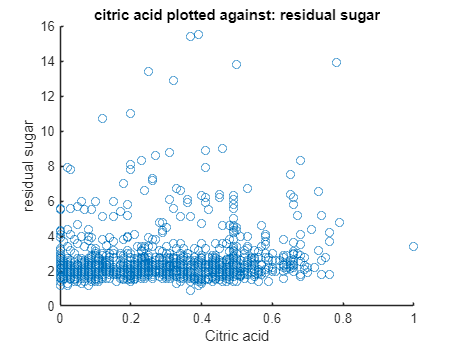

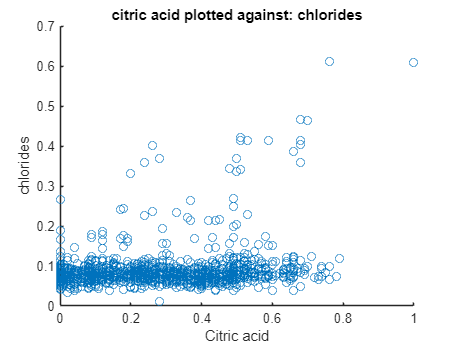

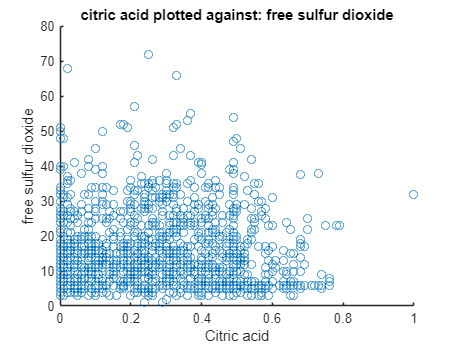

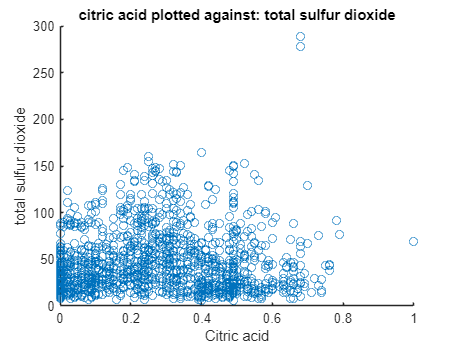

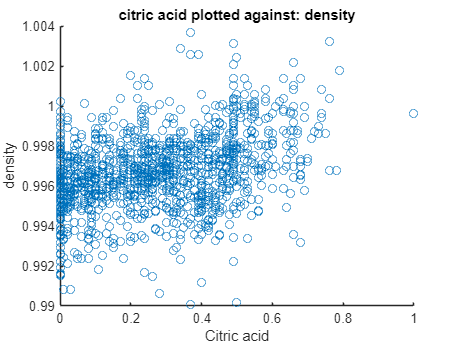

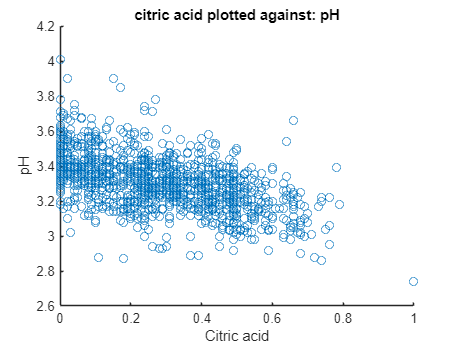

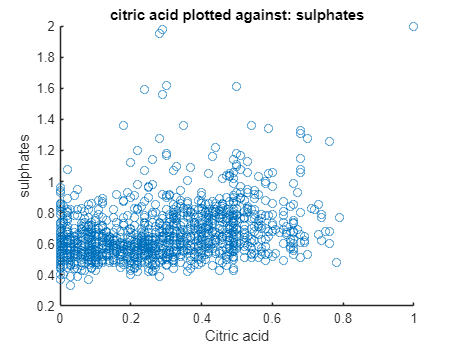

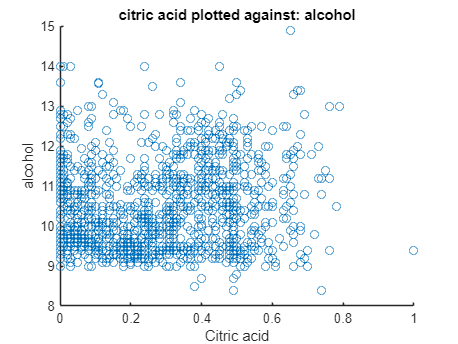

%% Citric acid
% Seems to be a central dominant variable as almost all data is linked with
% some correlation to it
for i = 1:length(header)
    figure;
    if wines.Properties.VariableNames{i} == "citric acid"
        continue
    end
     scatter(wines.("citric acid"), wines{:,i});
     xlabel('Citric acid');
     ylabel(header{i});
     title(['citric acid plotted against: ', header{i}]);

end

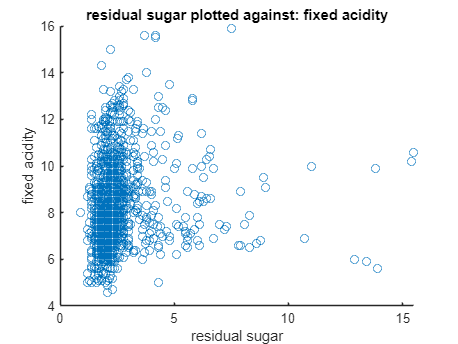

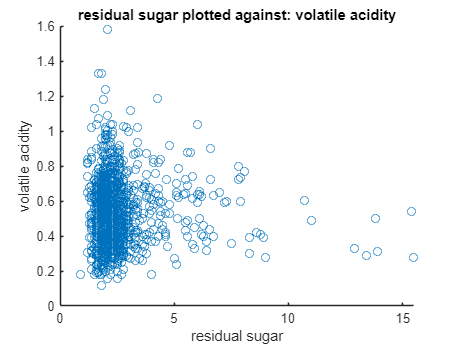

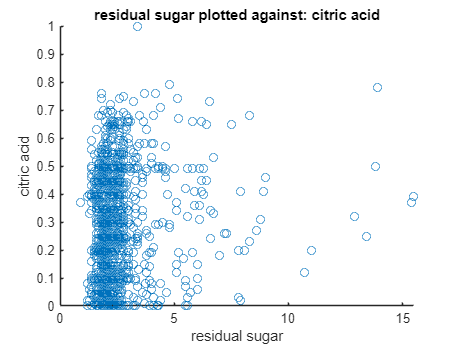

residual sugar


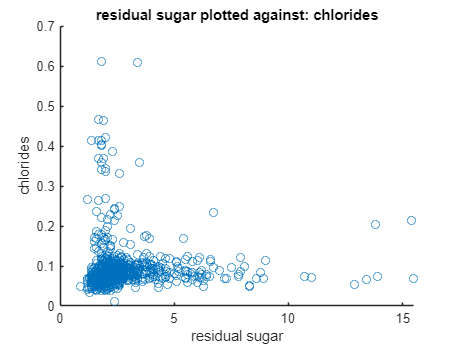

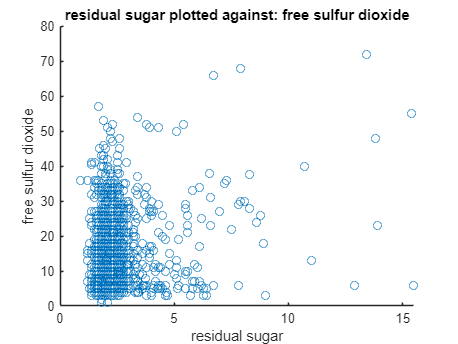

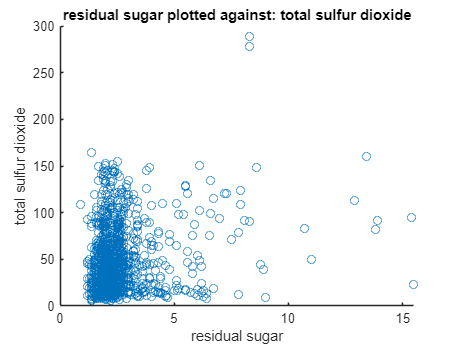

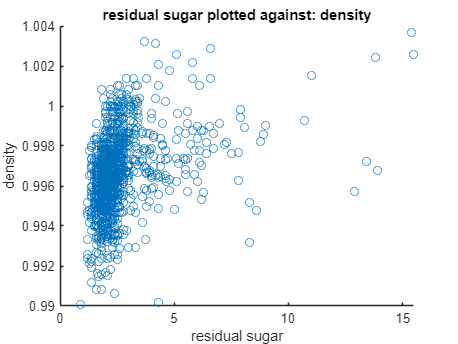

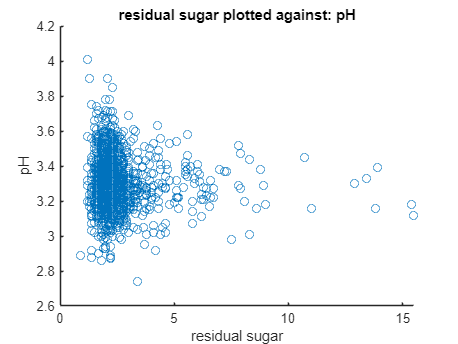

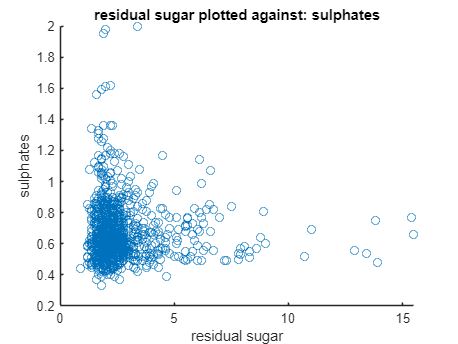

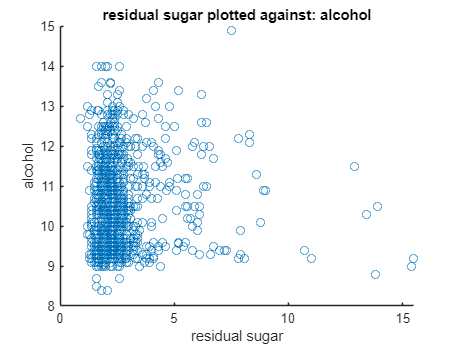

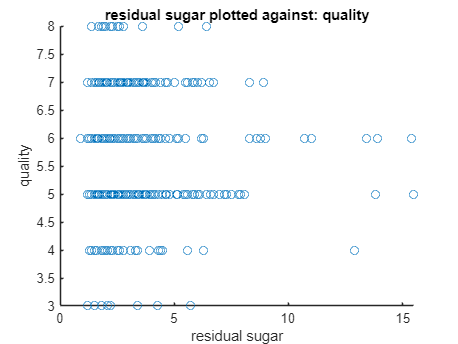

% residual sugar
 
for i = 1:length(header)
    figure;
    if wines.Properties.VariableNames{i} == "residual sugar"
        continue
    end
     scatter(wines.("residual sugar"), wines{:,i});
     xlabel('residual sugar');
     ylabel(header{i});
     title(['residual sugar plotted against: ', header{i}]);

end

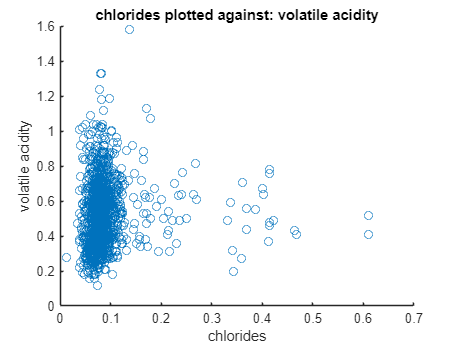

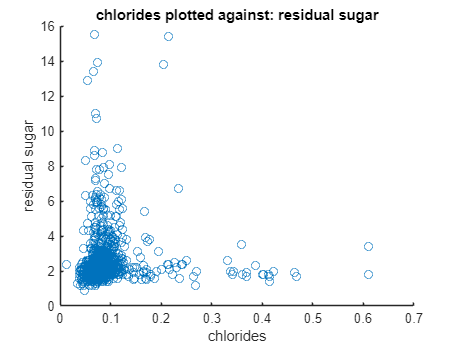

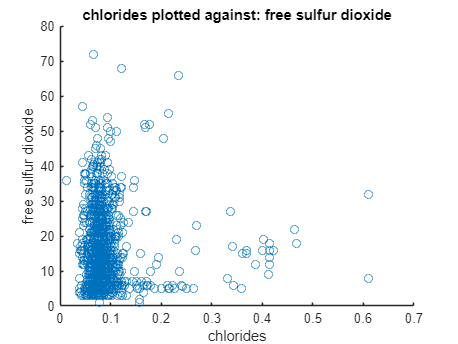

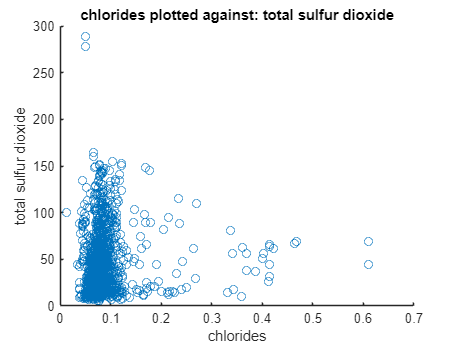

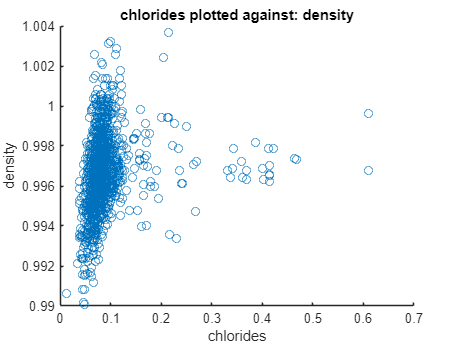

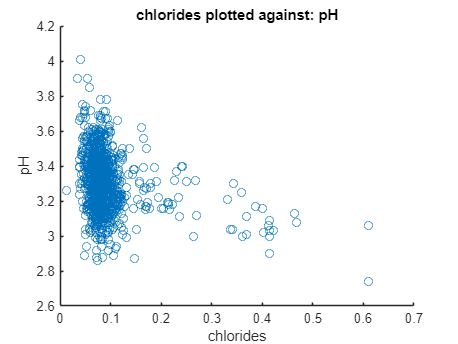

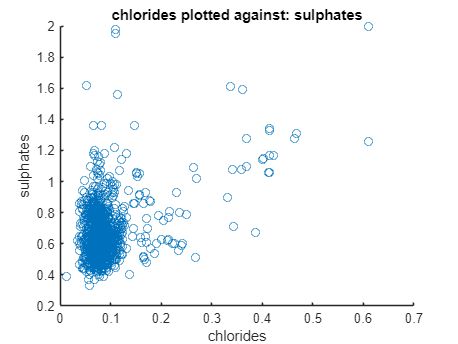

%% chlorides
% 
for i = 1:length(header)
    figure;
    if wines.Properties.VariableNames{i} == "chlorides"
        continue
    end
     scatter(wines.("chlorides"), wines{:,i});
     xlabel('chlorides');
     ylabel(header{i});
     title(['chlorides plotted against: ', header{i}]);

end

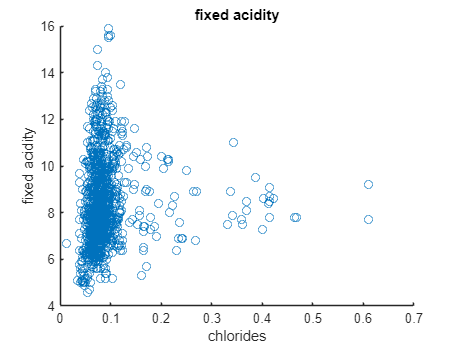

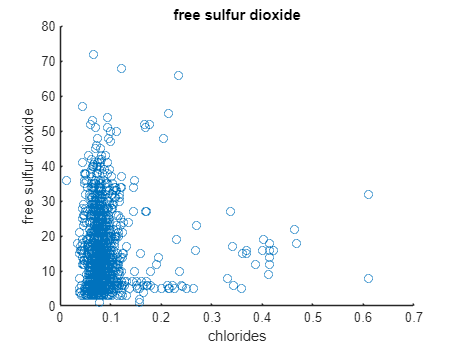

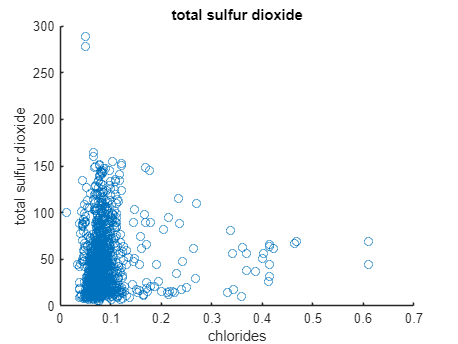

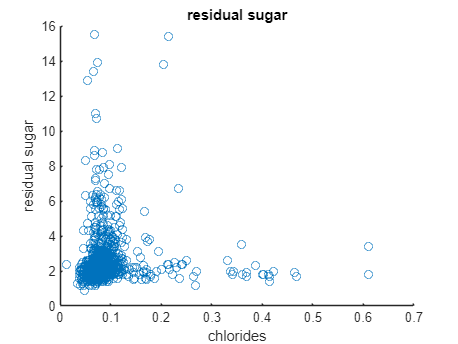

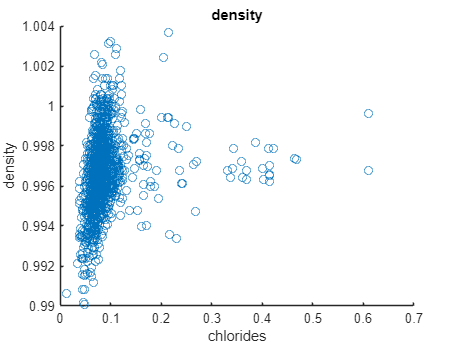

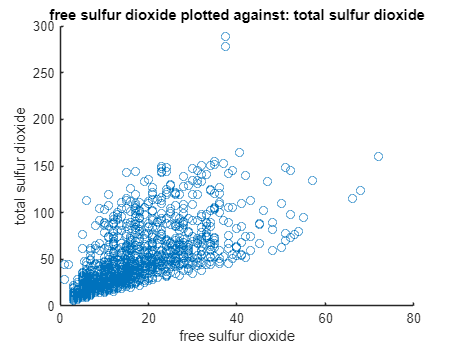

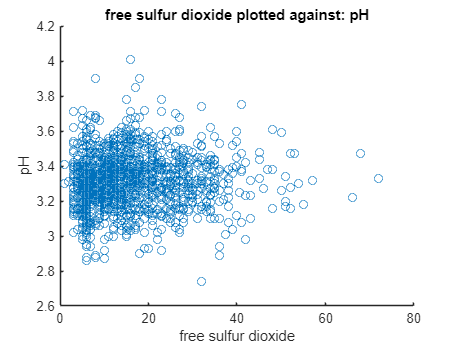

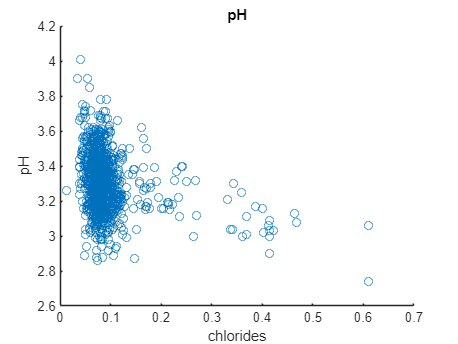

%% free sulfur dioxide
% Correlation obviously with total sulfur dioxide, could be combined 
for i = 1:length(header)
    figure;
    if wines.Properties.VariableNames{i} == "free sulfur dioxide"
        continue
    end
     scatter(wines.("free sulfur dioxide"), wines{:,i});
     xlabel('free sulfur dioxide');
     ylabel(header{i});
     title(['free sulfur dioxide plotted against: ', header{i}]);

end

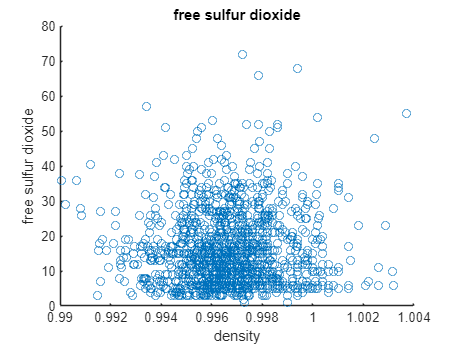

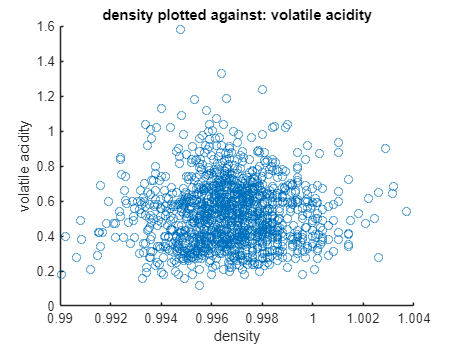

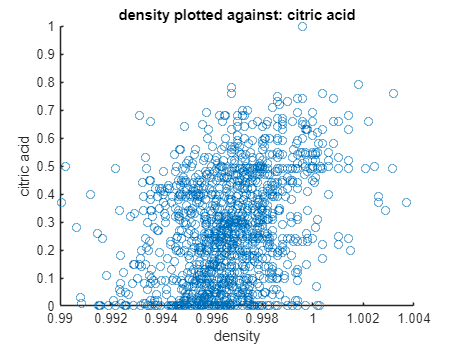

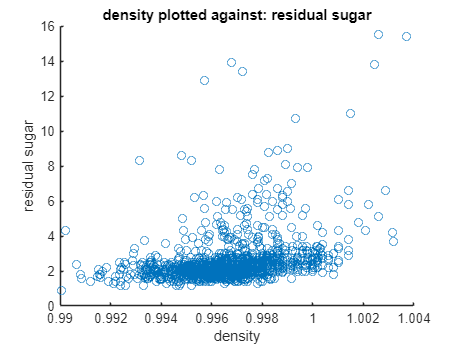

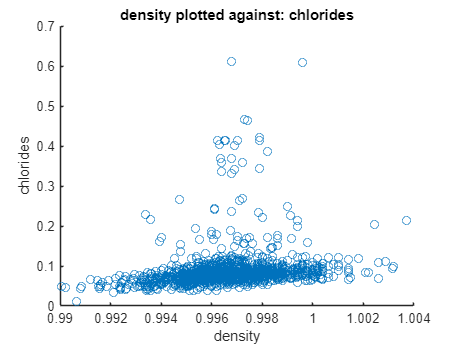

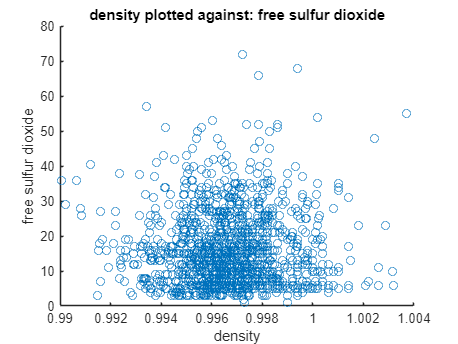

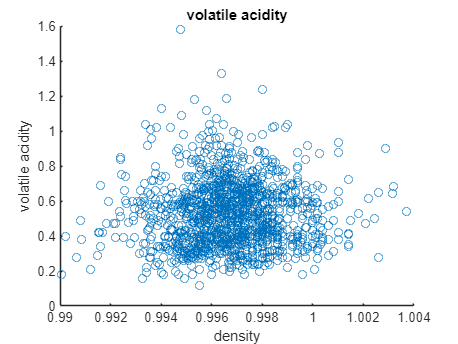

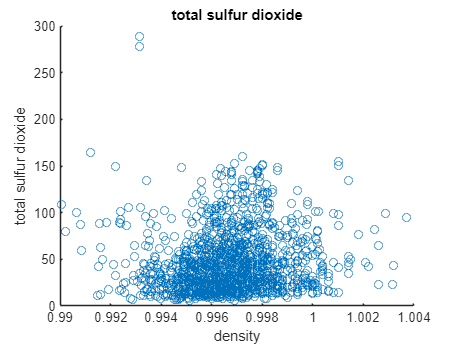

%% Density
%  Fixed acidity density (more acid, more dense), residual sugar, chlorides,pH (higher ph, less dense), alcohol
for i = 1:length(header)
    figure;
    if wines.Properties.VariableNames{i} == "density"
        continue
    end    
     scatter(wines.("density"), wines{:,i});
     xlabel('density');
     ylabel(header{i});
     title(['density plotted against: ', header{i}]);

end

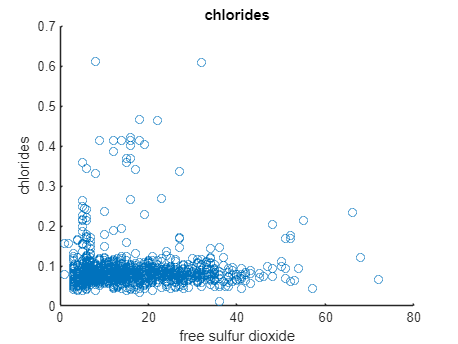

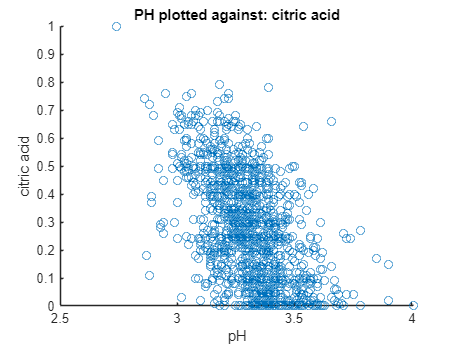

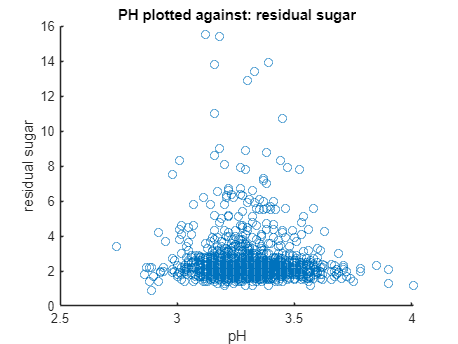

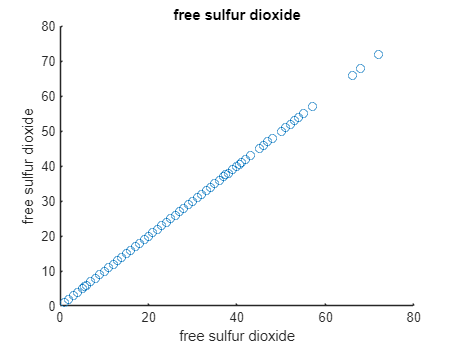

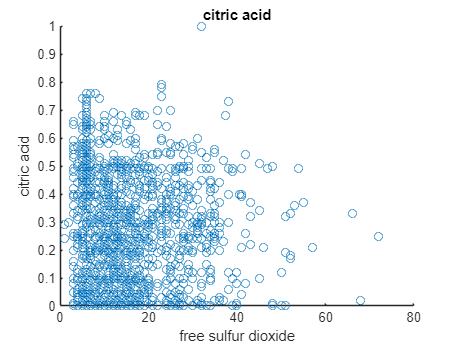

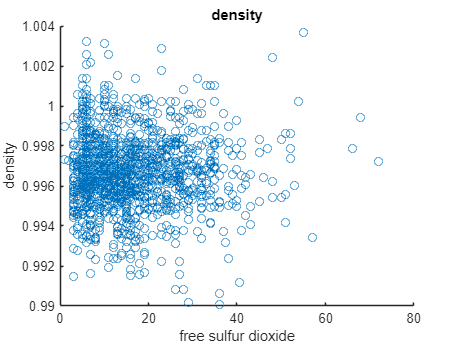

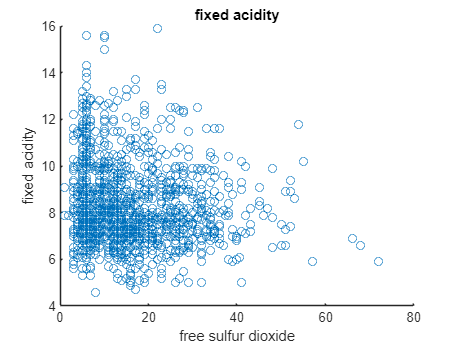

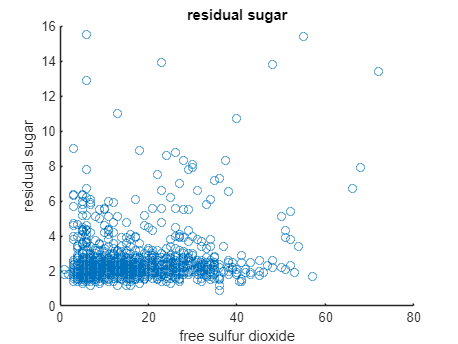

%% PH
%  Fixed acidity density (more acid, more dense), residual sugar, chlorides,pH (higher ph, less dense), alcohol
for i = 1:length(header)
    figure;
    if wines.Properties.VariableNames{i} == "pH"
        continue
    end    
     scatter(wines.("pH"), wines{:,i});
     xlabel('pH');
     ylabel(header{i});
     title(['PH plotted against: ', header{i}]);

end

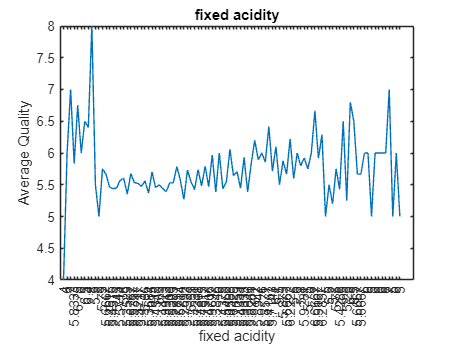

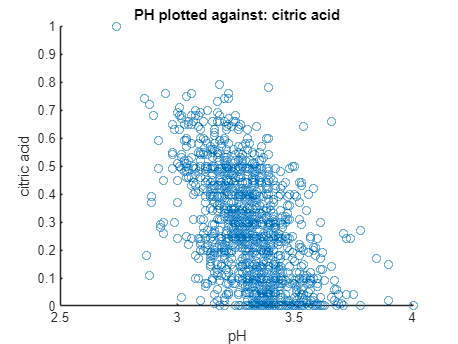

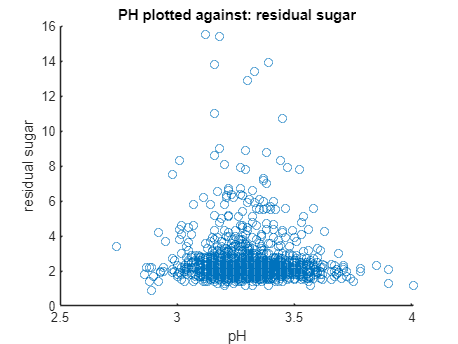

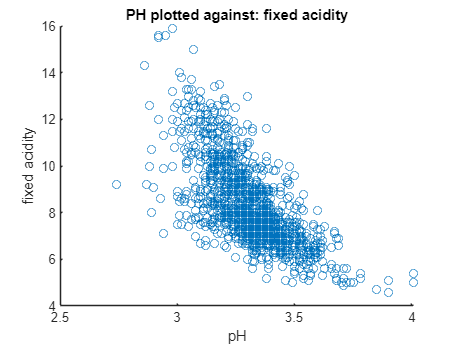

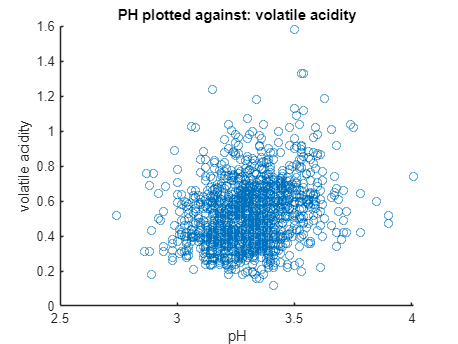

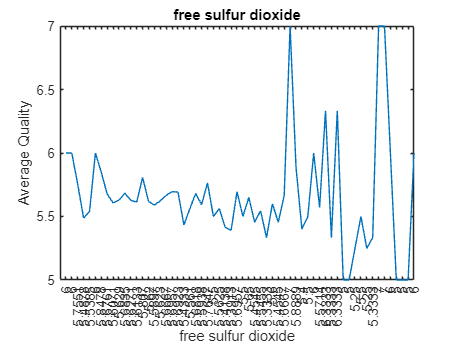

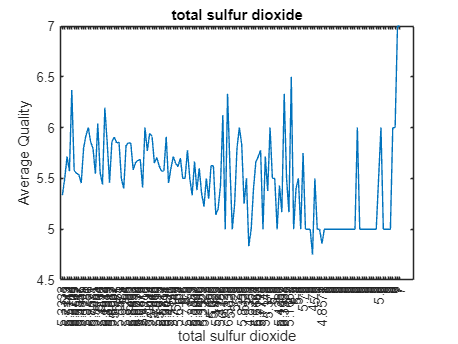

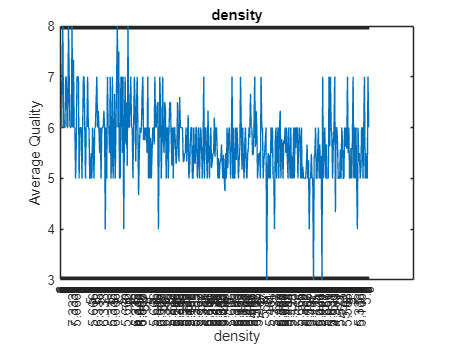

% Some average qualities
% Idea to see initial hypothesis
for i = 1:length(header)
    figure;
    [g, unique_value] = findgroups(wines.(i));
    avg_qual_in_i = splitapply(@mean, wines.("quality"), g);
    plot(avg_qual_in_i);
    set(gca, 'XTick', 1:length(avg_qual_in_i));
    set(gca, 'XTickLabel', string(avg_qual_in_i));
    xlabel(header{i});
    ylabel('Average Quality');
    title(header{i});
end

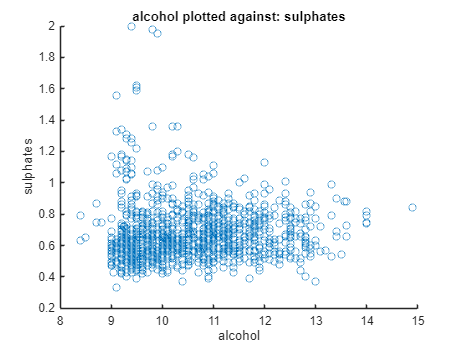

% Just a plot of alchool values against sulphates, no real idea behind this
figure;
scatter(wines.("alcohol"), wines.('sulphates'));
xlabel('alcohol');
ylabel('sulphates');
title(['alcohol plotted against: ','sulphates']);

## PCA - Fixed acidity

% Reread to skip header - personal simplicity not actually something that
% needs doing
X = readmatrix("winequality-red.csv","NumHeaderLines",1);
X = X(:, 1:end-1); % We are looking for quality so extract it?

% Scale and center data
mean_wines = mean(X);
centered_data = X - mean_wines;
std_wines = std(centered_data);
scaled_wines = centered_data ./ std_wines;

% PCA on scaled dataset
[coeff, score, latent, tsquared, explained, mu] = pca(scaled_wines);

% Extract the loadings for the first principal component
pc1_loadings = coeff(:, 1);
pc2_loadings = coeff(:, 2);

% Print out what the loadings are of PC1
fprintf('1st pC:\n');

1st pC:


for i = 1:length(header{1,end-2})
    fprintf('%s: %.4f\n', header{i}, pc1_loadings(i));
end

fixed acidity: 0.4893
volatile acidity: -0.2386
citric acid: 0.4636
residual sugar: 0.1461
chlorides: 0.2122
free sulfur dioxide: -0.0362
total sulfur dioxide: 0.0236


% Print out what the loadings are of PC2
fprintf('2nd pC:\n');

2nd pC:


for i = 1:length(1:length(header{1,end-2}))
    fprintf('%s: %.4f\n', header{i}, pc2_loadings(i));
end

fixed acidity: -0.1105
volatile acidity: 0.2749
citric acid: -0.1518
residual sugar: 0.2721
chlorides: 0.1481
free sulfur dioxide: 0.5136
total sulfur dioxide: 0.5695


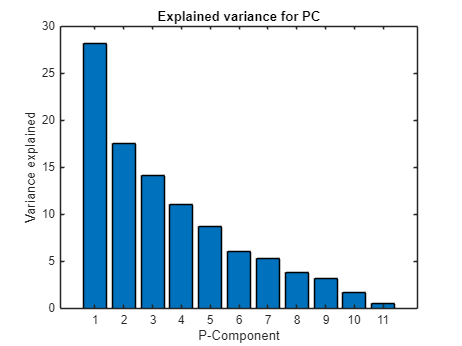

% Explained variance by PC
figure;
bar(explained);
xlabel('P-Component');
ylabel('Variance explained');
title('Explained variance for PC');

% Looks like 5 first components create the best results. Need to understand
% more

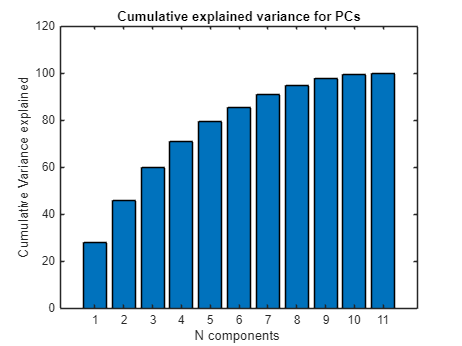

% Cumulative variance - Plotted to see total explanation of combination of
% PC's
cumulative_variance = cumsum(explained);
bar(cumulative_variance);
xlabel('N components ');
ylabel('Cumulative Variance explained');
title('Cumulative explained variance for PCs');

% 6-8 components seem to explain 80-90% of the variance

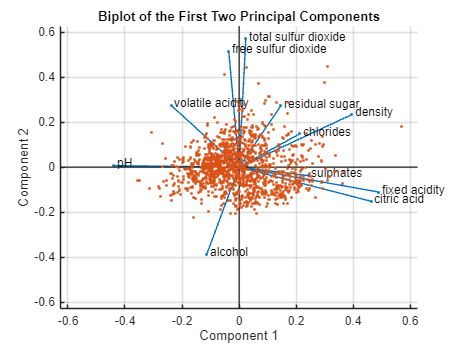

% Biplot
varlabels = wines.Properties.VariableNames(1:end-2);
figure;
% Biplot of two first PC's shows no correlation between alcohol and ph, fixed acidity,
% citric acidity, and sulphates

% Negative correlation between alcohol and, volatile acidity, free sulfur
% dioxide, residual sugar, density, and chlorides

biplot(coeff(:,1:2), 'Scores', score(:,1:2), 'VarLabels', varlabels);
title('Biplot of the First Two Principal Components');

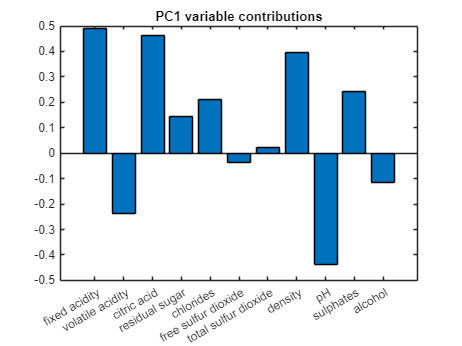

% Loading barplot PC 1

figure;
bar(coeff(:,1));
xticklabels(header);
title('PC1 variable contributions')

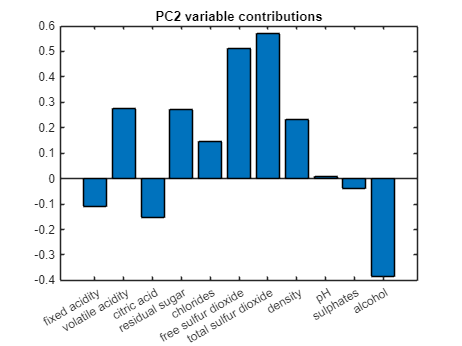

% Loading barplot PC 2

figure;
bar(coeff(:,2));
xticklabels(header);
title('PC2 variable contributions')



%for i = 1:length(header)
%    figure;
%    bar(coeff(:,i));
%    xticklabels(header);
%    title(header{i})

%end

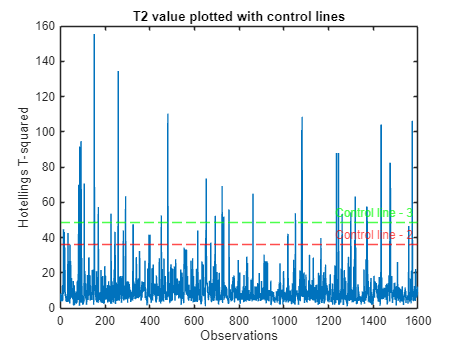

% T2 -plot

% Mean and std
mean_t2 = mean(tsquared);
std_t2 = std(tsquared);
t2_control_at_2 = mean_t2 + 2 * std_t2;
t2_control_at_3 = mean_t2 + 3 * std_t2;

figure;
plot(tsquared);
xlabel('Observations');
ylabel('Hotellings T-squared');
hold on;
yline(t2_control_at_2,'--r', 'Control line - 2');
yline(t2_control_at_3,'--g', 'Control line - 3');
title('T2 value plotted with control lines');

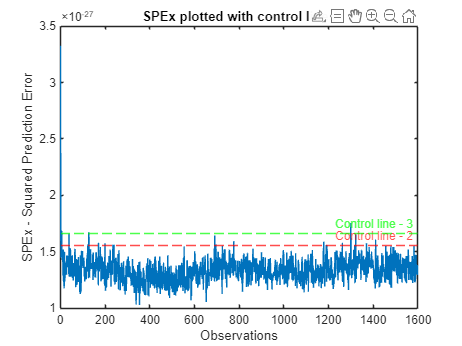

% SPEx

data_reconstruction = score* coeff';
error = scaled_wines - data_reconstruction;
SPE = sum(error.^2, 2);

mean_spe = mean(SPE);
std_SPE = std(SPE);
spe_2_control = mean_spe + 2 * std_SPE;
spe_3_control = mean_spe + 3 * std_SPE;

figure;
plot(SPE);
xlabel('Observations');
ylabel('SPEx - Squared Prediction Error');
hold on;
yline(spe_2_control,'--r', 'Control line - 2');
yline(spe_3_control,'--g', 'Control line - 3');

title('SPEx plotted with control lines');

## PCA With quality included

% This was not actually used, just looking at different ideas of the data
with_qual_X = readmatrix("winequality-red.csv","NumHeaderLines",1);

mean_wines_qual = mean(with_qual_X);
centered_data_qual = with_qual_X - mean_wines_qual;
std_wines_qual = std(centered_data_qual);
scaled_wines_qual = centered_data_qual ./ std_wines_qual;

[coeff_q, score_q, latent_q, tsquared_q, explained_q, mu_q] = pca(scaled_wines_qual);

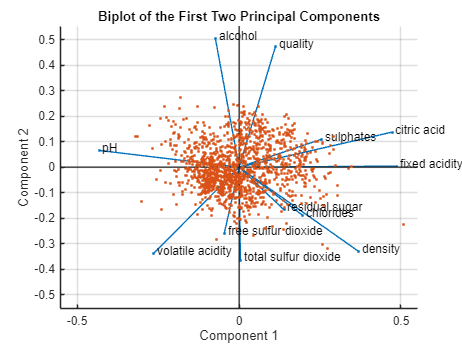

biplot(coeff_q(:,1:2), 'Scores', score_q(:,1:2), 'VarLabels', header(1:end-1));
title('Biplot of the First Two Principal Components');